# Ejercicio 1

Considera un haz láser Gaussiano. Como sabes, su expresión viene dada por:


$$E(\rho,z;k_{0})=E_0\frac{w_0}{w(z)}  \exp\left(-\frac{\rho^{2}}{w^{2}(z)}\right)\exp\left[-i \left(k_0z+\frac{k_{0}\rho^{2}}{2R(z)}-\Phi_{G}(z)\right)\right]$$


donde

$w(z)=w_{0}\sqrt{1+(z/z_{0})^{2}}$ es la anchura del haz, $w_0$ es la cintura en el foco (waist), y se define la distancia de Rayleigh como $z_{0}=k_{0}w^{2}_{0}/2$. $R(z)=z\left[1+(z_{0}/z)^{2}\right]$es el radio del haz, y $\Phi(z)=\arctan(z/z_{0})$es la fase de Gouy. Puedes encontrar más información sobre haces gaussianos en [Gaussian beam](https://en.wikipedia.org/wiki/Gaussian_beam).

Considera un haz Gaussiano con un waist de 30 micras y longitud de onda 800 nm. Representa:

- La anchura del haz frente la posición z a lo largo del eje de propagación.

- La fase de Gouy frente la posición z a lo largo del eje de propagación.

- El perfil radial de intensidad del campo eléctrico en distintas posiciones z a lo largo del eje de propagación (usa la orden *hold on, *y dibuja cada línea con un color distinto). Dibújalo tanto en escala lineal como en escala logarítmica.

- El perfil radial de la fase del campo eléctrico en distintas posiciones z a lo largo del eje de propagación (usa la orden *hold on, *y dibuja cada línea con un color distinto). 

- El perfil radial de intensidad y el perfil radial de fase, en una misma gráfica, en tres puntos del eje de propagación: en el foco, en $z_0/2$ y en $z_0$. Explora el uso de la función plotxy.

- ¿Sabrías repetir el apartado tres pero usando la función plot3? Mediante esta función podemos representar gráficas 2D en un entorno tridimensional.

Notas: Expresa el eje de propagación en función de la distancia de Rayleigh, y el eje transversal (anchura) en función del waist. Completa las gráficas con toda la información necesaria sobre etiquetas, ejes, leyendas, etc.

- La anchura del haz frente la posición z a lo largo del eje de propagación.

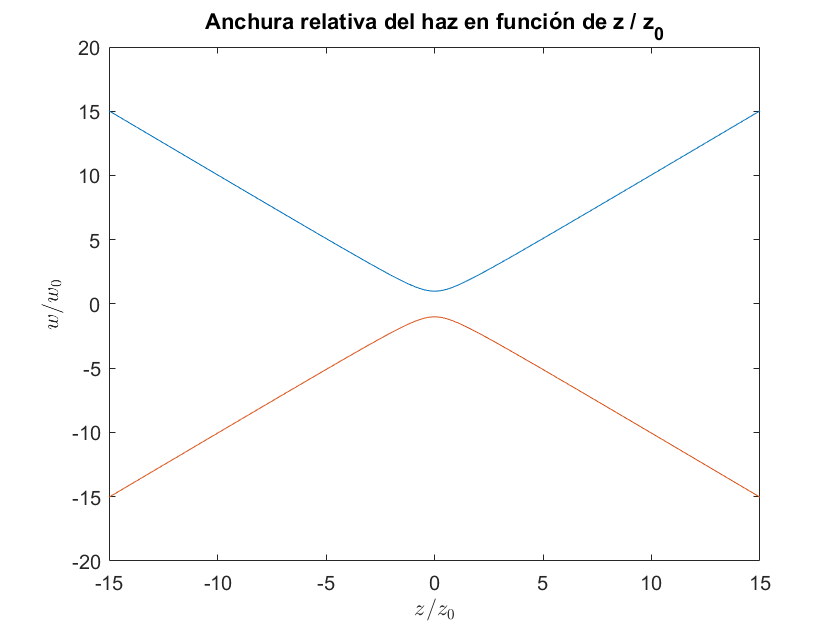

lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*w0^2/2;
z=-15*z0:0.2:15*z0; % Vector de z
w=w0*sqrt(1+(z/z0).^2); % Calculamos la anchura para distintos z
plot(z/z0,w/w0); % Graficamos
hold on; % Utilizamos esta función para que se representen 
% las dos gráficas a la vez
plot(z/z0,-w/w0);
hold off; % Ya no se mantienen más

% Título de la gráfica
title('Anchura relativa del haz en función de z / z_{0}', 'FontSize', 16, 'FontName', 'Helvetica');
% Título de los ejes
xlabel('$ z / z_{0} $', 'Interpreter','latex','FontSize', 12, 'FontName', 'Helvetica');
ylabel('$ w / w_{0} $', 'Interpreter','latex', 'FontSize', 12, 'FontName', 'Helvetica');
% Editamos los ejes actuales: get current axes
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');

-  La fase de Gouy frente la posición z a lo largo del eje de propagación.

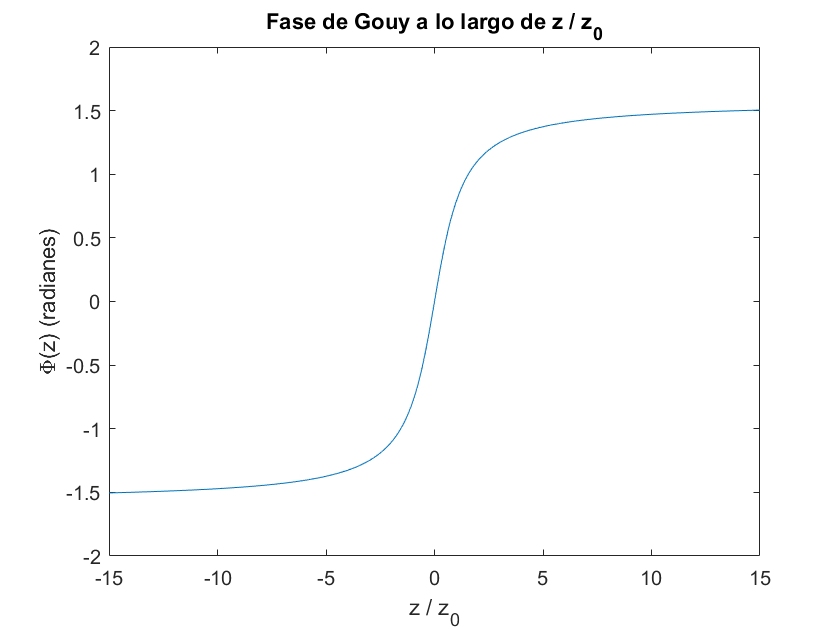

% Barremos z y dibujamos la fase de Goy para cada posición
fi=atan(z/z0);
plot(z/z0,fi);

title('Fase de Gouy a lo largo de z / z_{0}', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('\Phi(z) (radianes)', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');

- El perfil radial de intensidad del campo eléctrico en distintas posiciones z a lo largo del eje de propagación (usa la orden *hold on, *y dibuja cada línea con un color distinto). Dibújalo tanto en escala lineal como en escala logarítmica.

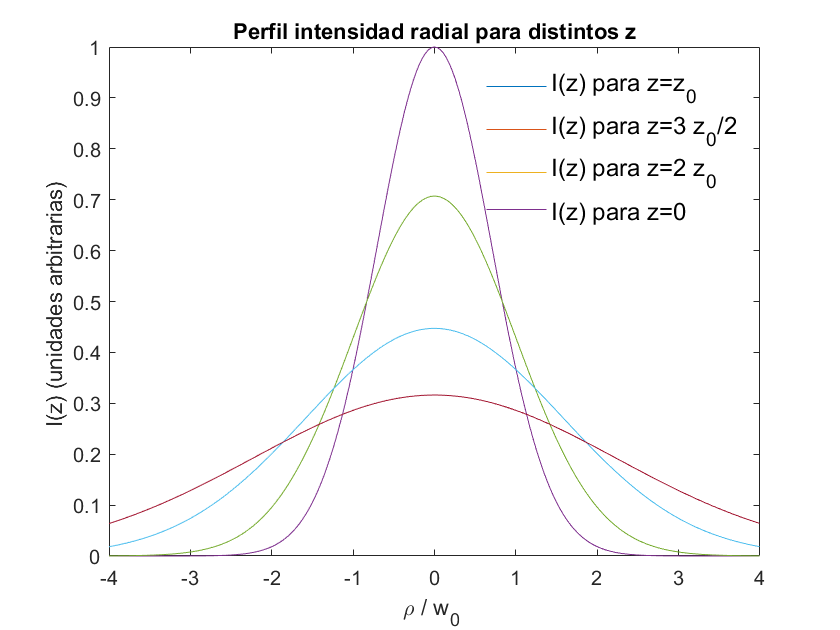

ro=-4*w0:1.1:4*w0;
e0=1;
z=(-3:3).*z0;
for j = 1:1:length(z) 
% j que va desde 1 hasta la longitud del vector z en pasos de 1
w=w0*sqrt(1+(z(j)/z0)^2); % Se accede a cada posición del vector z con j
e=e0*(w0/w)*exp(-(ro./w).^2); 
% Para cada posición de z se calcula w y se recorre el vector ro
plot(ro/w0,e); % Eje x:ro/wo y eje y: e
hold on;
end
hold off;

title('Perfil intensidad radial para distintos z', 'FontSize', 16, 'FontName', 'Helvetica');
% Leyenda. Su representación coincide con el orden en el que barremos z
legend('I(z) para z=z_0', 'I(z) para z=3 z_0/2', 'I(z) para z=2 z_0', 'I(z) para z=0', 'Location', 'northeast','FontSize', 12, 'FontName', 'Helvetica');
legend('boxoff'); % Quitamos el rectángulo donde está inscrita la leyenda
xlabel('\rho / w_{0} ', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('I(z) (unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');


for j = 1:1:length(z)
w=w0*sqrt(1+(z(j)/z0)^2);
e=e0*(w0/w)*exp(-(ro./w).^2);
semilogx(ro/w0,e); % Representación logarítmica del caso anteior
hold on;

end
hold off;

title('Perfil intensidad radial para distintos z', 'FontSize', 16, 'FontName', 'Helvetica');

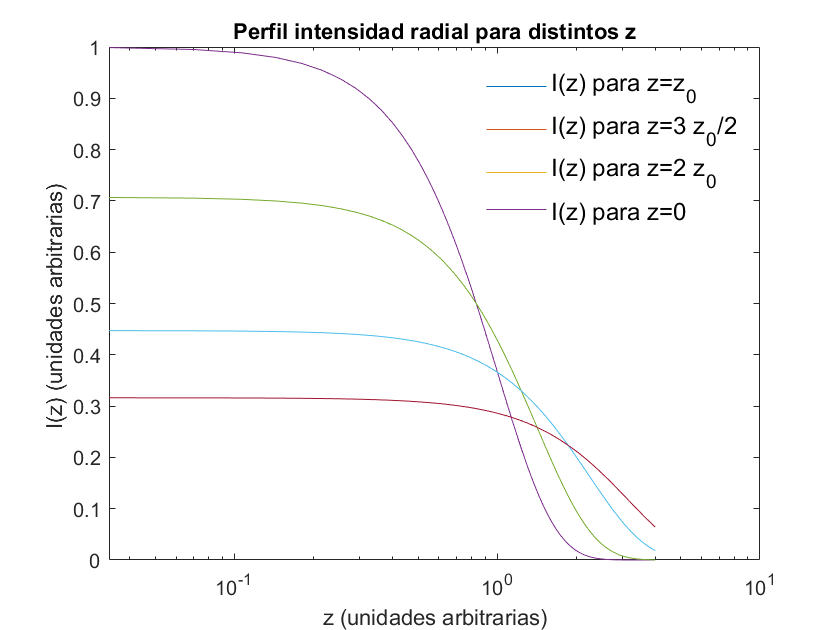

legend('I(z) para z=z_0', 'I(z) para z=3 z_0/2', 'I(z) para z=2 z_0', 'I(z) para z=0', 'Location', 'northeast','FontSize', 12, 'FontName', 'Helvetica');
legend('boxoff');
xlabel('z (unidades arbitrarias)', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('I(z) (unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');

-  El perfil radial de la fase del campo eléctrico en distintas posiciones z a lo largo del eje de propagación (usa la orden *hold on, *y dibuja cada línea con un color distinto). 

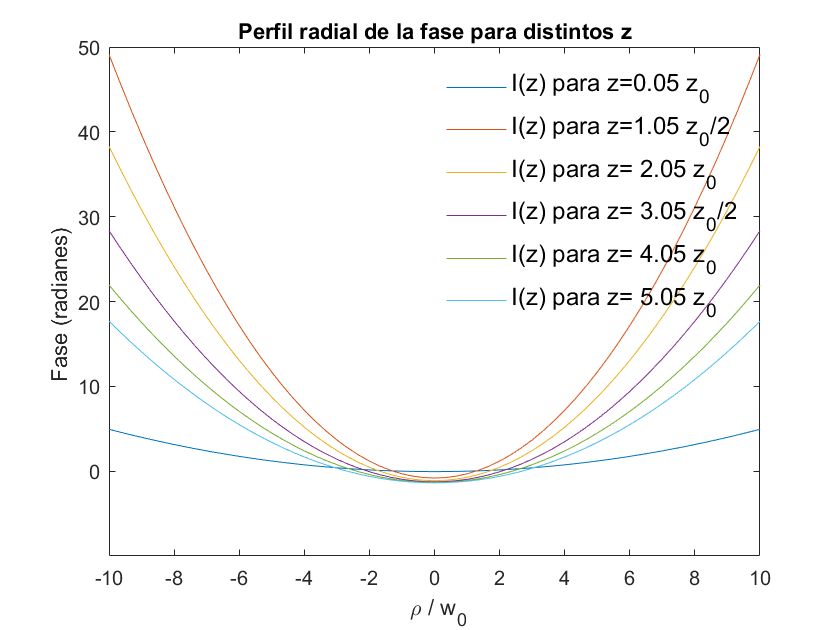

%%Parte 4
ro=-10*w0:10:10*w0;
z=(0.05:1:5.05).*z0; 
for j = 1:1:length(z)
fi=atan(z(j)/z0);
r=(1+(z0/z(j))^2)*z(j);
w=w0*sqrt(1+(z(j)/z0)^2);
fase=((k0.*((ro).^2)./(2*r))-fi);
plot(ro/w0,fase);
hold on;
end
hold off;

title('Perfil radial de la fase para distintos z', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('Fase (radianes) ', 'FontSize', 12, 'FontName', 'Helvetica');
legend('I(z) para z=0.05 z_0', 'I(z) para z=1.05 z_0', 'I(z) para z= 2.05 z_0', 'I(z) para z= 3.05 z_0','I(z) para z= 4.05 z_0','I(z) para z= 5.05 z_0', 'Location', 'northeast','FontSize', 12, 'FontName', 'Helvetica');
legend('boxoff');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
set(gca,'XTick',-10:2:10);
set(gca,'YTick',0:10:50);

- El perfil radial de intensidad y el perfil radial de fase, en una misma gráfica, en tres puntos del eje de propagación: en el foco, en $z_0/2$ y en $z_0$. Explora el uso de la función plotxy.

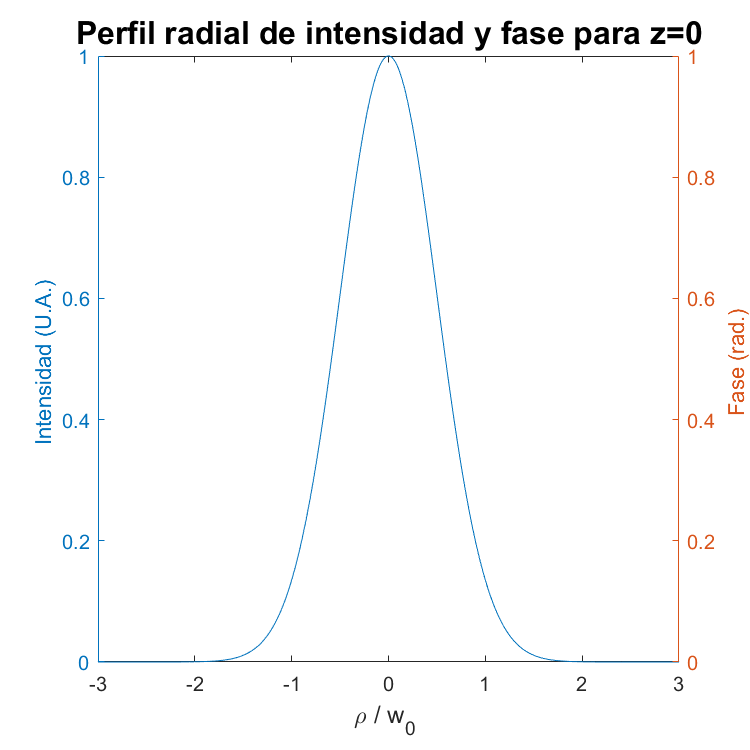

lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*w0^2/2;
e0=1;

ro=(-110:0.05:110);
z=0;
fi=atan(z/z0);
r=(1+(z0/z)^2)*z;
fase=((k0.*((ro).^2)./(2*r))-fi);
w=w0*sqrt(1+(z/z0)^2);
e=e0*(w0/w)*exp(-(ro./w).^2);

figure; % La gráfica se guarda como figura
[hAx,hLine1,hLine2] = plotyy(ro/w0,e.^2,ro/w0,fase); % Denifimos las líneas y los ejes de la gráfica
title('Perfil radial de intensidad y fase para z=0', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('\rho / w_{0} ', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(hAx(1),'Intensidad (U.A.) ', 'FontSize', 11, 'FontName', 'Helvetica'); % Eje y izquierda
ylabel(hAx(2),'Fase (rad.) ', 'FontSize', 11, 'FontName', 'Helvetica'); % Eje y derecha 
hLine1.LineStyle = '-';
hLine2.LineStyle = '--';
xlim([-3 3]) % Límite de representación en x
set(gcf,'Position',[100 100 500 500]); % Tamaño de la figura
drawnow; % Dibuja ahora

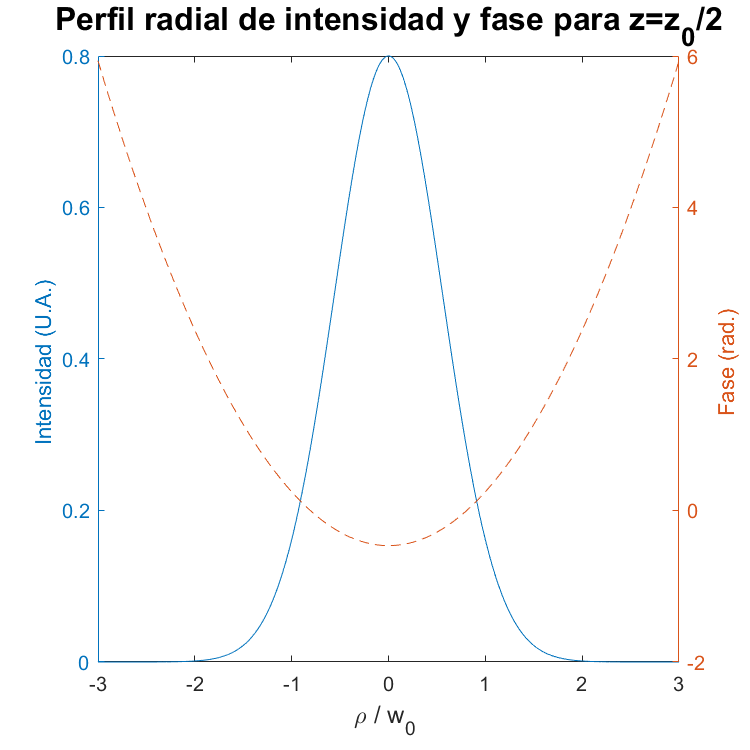


z=z0/2;
ro=(-120:0.05:120);
fi=atan(z/z0);
r=(1+(z0/z)^2)*z;
fase=((k0.*((ro).^2)./(2*r))-fi);
w=w0*sqrt(1+(z/z0)^2);
e=e0*(w0/w)*exp(-(ro./w).^2);

figure;
[hAx,hLine1,hLine2] = plotyy(ro/w0,e.^2,ro/w0,fase);
title('Perfil radial de intensidad y fase para z=z_0/2', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('\rho / w_{0} ', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(hAx(1),'Intensidad (U.A.) ', 'FontSize', 11, 'FontName', 'Helvetica');
ylabel(hAx(2),'Fase (rad.) ', 'FontSize', 11, 'FontName', 'Helvetica'); 
hLine1.LineStyle = '-';
hLine2.LineStyle = '--';
xlim([-3 3])
set(gcf,'Position',[100 100 500 500]);
drawnow ;

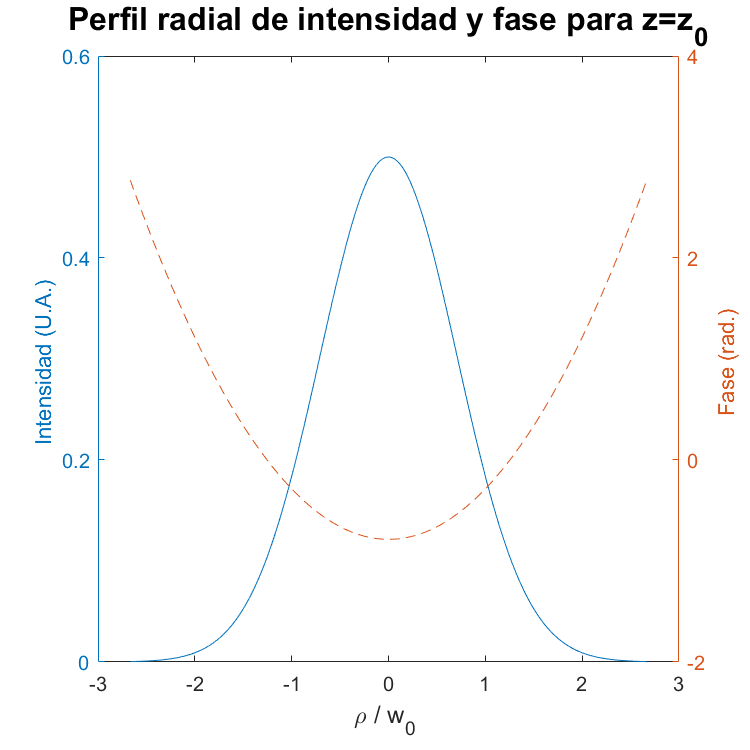


z=z0;
ro=(-80:0.05:80);
fi=atan(z/z0);
r=(1+(z0/z)^2)*z;
fase=((k0.*((ro).^2)./(2*r))-fi);
w=w0*sqrt(1+(z/z0)^2);
e=e0*(w0/w)*exp(-(ro./w).^2);

figure;
[hAx,hLine1,hLine2] = plotyy(ro/w0,e.^2,ro/w0,fase);
title('Perfil radial de intensidad y fase para z=z_0', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('\rho / w_{0} ', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(hAx(1),'Intensidad (U.A.) ', 'FontSize', 11, 'FontName', 'Helvetica');
ylabel(hAx(2),'Fase (rad.) ', 'FontSize', 11, 'FontName', 'Helvetica'); 
hLine1.LineStyle = '-';
hLine2.LineStyle = '--';
xlim([-3 3])

set(gcf,'Position',[100 100 500 500]);
drawnow;

- ¿Sabrías repetir el apartado tres pero usando la función plot3? Mediante esta función podemos representar gráficas 2D en un entorno tridimensional

lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*w0^2/2;
e0=1;

% Para cada z me interesa tener muchos puntos de ro
% Tengo un problema de dimensiones al representar el plot3
ro= (-3:0.1:3)*w0

ro =   -90.0000  -87.0000  -84.0000  -81.0000  -78.0000  -75.0000  -72.0000  -69.0000  -66.0000  -63.0000  -60.0000  -57.0000  -54.0000  -51.0000  -48.0000  -45.0000  -42.0000  -39.0000  -36.0000  -33.0000  -30.0000  -27.0000  -24.0000  -21.0000  -18.0000  -15.0000  -12.0000   -9.0000   -6.0000   -3.0000         0    3.0000    6.0000    9.0000   12.0000   15.0000   18.0000   21.0000   24.0000   27.0000   30.0000   33.0000   36.0000   39.0000   42.0000   45.0000   48.0000   51.0000   54.0000   57.0000


z=[0 1/2 1 3/2 2];
% Utilizamos linspace que genera n puntos
% El espaciado entre los puntos es (x2-x1)/(n-1).
zz=linspace(-2,2,61);

for j = 1:1:length(z)
w=w0*sqrt(1+(z(j))^2); % Sólo cojo las posiciones del vector z
e=e0*(w0/w)*exp(-(ro./w).^2); 
% Para cada posición de z calculo el e de todos los elemetos de ro: 61
inten=e.^2 
plot3(ro/w0,zz,inten); 
% Represento los vectores ro, zz e inten (tienen la misma dimensión)
% para una posición de z
% Hago lo mismo en cada iteración del bucle y las represento juntas
hold on;
end

inten =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0007    0.0015    0.0031    0.0060    0.0111    0.0198    0.0340    0.0561    0.0889    0.1353    0.1979    0.2780    0.3753    0.4868    0.6065    0.7261    0.8353    0.9231    0.9802    1.0000    0.9802    0.9231    0.8353    0.7261    0.6065    0.4868    0.3753    0.2780    0.1979    0.1353    0.0889    0.0561    0.0340    0.0198    0.0111    0.0060    0.0031    0.0015    0.0007


inten =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0025    0.0045    0.0079    0.0133    0.0219    0.0348    0.0535    0.0799    0.1154    0.1615    0.2189    0.2873    0.3653    0.4497    0.5363    0.6193    0.6927    0.7504    0.7873    0.8000    0.7873    0.7504    0.6927    0.6193    0.5363    0.4497    0.3653    0.2873    0.2189    0.1615    0.1154    0.0799    0.0535    0.0348    0.0219    0.0133    0.0079    0.0045    0.0025


inten =     0.0001    0.0001    0.0002    0.0003    0.0006    0.0010    0.0016    0.0025    0.0040    0.0061    0.0092    0.0135    0.0196    0.0278    0.0387    0.0527    0.0704    0.0923    0.1185    0.1491    0.1839    0.2224    0.2636    0.3063    0.3488    0.3894    0.4261    0.4570    0.4804    0.4950    0.5000    0.4950    0.4804    0.4570    0.4261    0.3894    0.3488    0.3063    0.2636    0.2224    0.1839    0.1491    0.1185    0.0923    0.0704    0.0527    0.0387    0.0278    0.0196    0.0135


inten =     0.0012    0.0017    0.0025    0.0035    0.0048    0.0066    0.0089    0.0119    0.0157    0.0204    0.0262    0.0334    0.0419    0.0520    0.0637    0.0771    0.0921    0.1088    0.1268    0.1461    0.1663    0.1869    0.2075    0.2276    0.2465    0.2638    0.2788    0.2911    0.3002    0.3058    0.3077    0.3058    0.3002    0.2911    0.2788    0.2638    0.2465    0.2276    0.2075    0.1869    0.1663    0.1461    0.1268    0.1088    0.0921    0.0771    0.0637    0.0520    0.0419    0.0334


inten =     0.0055    0.0069    0.0087    0.0108    0.0134    0.0164    0.0200    0.0241    0.0289    0.0343    0.0404    0.0472    0.0547    0.0629    0.0718    0.0813    0.0913    0.1017    0.1124    0.1233    0.1341    0.1447    0.1548    0.1644    0.1732    0.1810    0.1876    0.1929    0.1968    0.1992    0.2000    0.1992    0.1968    0.1929    0.1876    0.1810    0.1732    0.1644    0.1548    0.1447    0.1341    0.1233    0.1124    0.1017    0.0913    0.0813    0.0718    0.0629    0.0547    0.0472


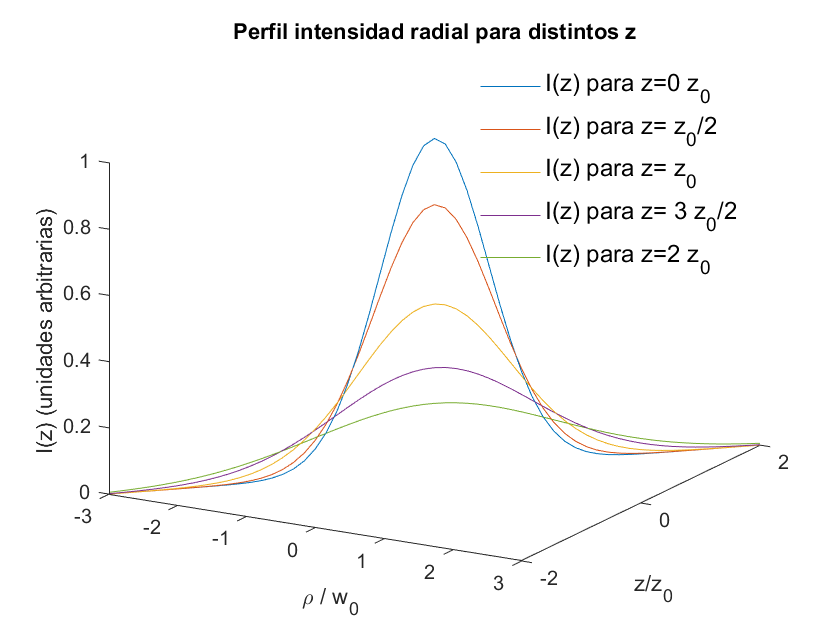

hold off;

title('Perfil intensidad radial para distintos z', 'FontSize', 16, 'FontName', 'Helvetica');
legend('I(z) para z=0 z_0', 'I(z) para z= z_0/2', 'I(z) para z= z_0', 'I(z) para z= 3 z_0/2','I(z) para z=2 z_0', 'Location', 'northeast','FontSize', 12, 'FontName', 'Helvetica');
legend('boxoff');
xlabel('\rho / w_{0} ', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('I(z) (unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('z/z_0 ', 'FontSize', 11, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
view([30 22]); % La representación 3D de ve desde estos ángulos